# Problema 5 - Suplimentara

# 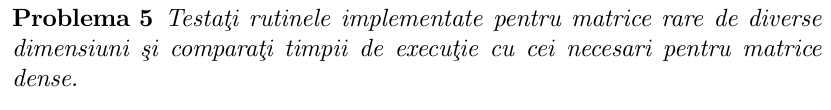

### Metoda Jacobi

%PB 1
function [aprox, num_iteratii] = metoda_jacobi(A, b, tol, iter_max)
    n = size(A, 1);                 
    x_vechi = zeros(n, 1);           
    aprox = zeros(n, 1);             
    num_iteratii = 0;                

    while num_iteratii < iter_max
        for i = 1:n
            suma = 0;
            for j = 1:n
                if j ~= i
                    suma = suma + A(i,j) * x_vechi(j);
                end
            end
            aprox(i) = (b(i) - suma) / A(i,i);
        end
        if norm(aprox - x_vechi, inf) < tol
            break;
        end
        x_vechi = aprox;
        num_iteratii = num_iteratii + 1;
    end
end

### Metoda SOR + Gauss-Seidel

%PB2
function [solutie, nr_iteratii] = metoda_sor(A, b, w, tol, iter_max)
    n = length(b);
    x = zeros(n, 1);             
    nr_iteratii = 0;

    while nr_iteratii < iter_max
        x_vechi = x;             

        for i = 1:n
            s = A(i,:) * x - A(i,i) * x(i);   

            x(i) = (1 - w) * x_vechi(i) + w * (b(i) - s) / A(i,i);
        end

        nr_iteratii = nr_iteratii + 1;
        if norm(x - x_vechi, inf) < tol
            break;
        end
    end

    solutie = x;
end
function w_opt = calculeaza_omega_opt(A)
    D = diag(diag(A));
    L = tril(A, -1);
    U = triu(A, 1);

    T = -inv(D) * (L + U);
    p = max(abs(eig(T)));

    if p >= 1
        warning("Jacobi nu converge, ω optim nu poate fi estimat.");
        w_opt = NaN;
    else
        w_opt = 2 / (1 + sqrt(1 - p^2));
    end
end

## Functia de generare a matricelor

5	-1	0	0

-1	5	-1	0

0	-1	5	-1

0	0	-1	5

0	0	0	-1

function [A_sparse, A_dense, b] = generare_sistem_test(n)
    % Construim o matrice tridiagonala pentru sistem sparse
    main_diag = 5 * ones(n, 1);
    off_diag = -1 * ones(n-1, 1);
    
    A = diag(main_diag) + diag(off_diag, -1) + diag(off_diag, 1);
    
    A_sparse = sparse(A);    % varianta rara
    A_dense = full(A);        % varianta densa
    
    b = ones(n, 1);           % solutie vector [1,1,...,1]
end

function testare_metode_sparse_dense()
    dimensiuni = [100, 200, 500, 1000];
    tol = 1e-6; 
    max_iter = 10000;

    fprintf('%6s | %12s | %12s | %12s | %12s | %12s | %12s\n', ...
        'n', 'Jacobi_sparse', 'Jacobi_dense', 'SOR_sparse', 'SOR_dense', 'SOR_opt_sparse', 'SOR_opt_dense');

    for n = dimensiuni
        [As, Ad, b] = generare_sistem_test(n);
        omega = 1.5;

        % Jacobi - sparse
        tic;
        [~, ~] = metoda_jacobi(As, b, tol, max_iter);
        t_js = toc;

        % Jacobi - dense
        tic;
        [~, ~] = metoda_jacobi(Ad, b, tol, max_iter);
        t_jd = toc;

        % SOR - sparse
        tic;
        [~, ~] = metoda_sor(As, b, omega, tol, max_iter);
        t_ss = toc;

        % SOR - dense
        tic;
        [~, ~] = metoda_sor(Ad, b, omega, tol, max_iter);
        t_sd = toc;

        % SOR cu omega optim – calculăm pe varianta densă (dar îl folosim și la sparse)
        omega_opt = calculeaza_omega_opt(Ad);  % putem folosi As la fel

        % SOR optim - sparse
        tic;
        [~, ~] = metoda_sor(As, b, omega_opt, tol, max_iter);
        t_sopt_s = toc;

        % SOR optim - dense
        tic;
        [~, ~] = metoda_sor(Ad, b, omega_opt, tol, max_iter);
        t_sopt_d = toc;

        % Afișare rezultate
        fprintf('%6d | %12.4f | %12.4f | %12.4f | %12.4f | %14.4f | %14.4f\n', ...
            n, t_js, t_jd, t_ss, t_sd, t_sopt_s, t_sopt_d);
    end
end

testare_metode_sparse_dense

     n | Jacobi_sparse | Jacobi_dense |   SOR_sparse |    SOR_dense | SOR_opt_sparse | SOR_opt_dense
   100 |       0.2764 |       0.0040 |       0.0194 |       0.0040 |         0.0052 |         0.0003
   200 |       1.1196 |       0.0021 |       0.0266 |       0.0019 |         0.0091 |         0.0005
   500 |       8.1701 |       0.0200 |       0.1178 |       0.0118 |         0.0469 |         0.0026
  1000 |      35.1690 |       0.0742 |       0.3526 |       0.0505 |         0.1026 |         0.0132


#### Exemplu de stocare a celor 2 matrici

% Matrice densa
A_dense = [5 -1 0; -1 5 -1; 0 -1 5];

% Matrice rara
A_sparse = sparse(A_dense);  % exact aceleași valori, dar stocare eficientă
